# `copyUIAxes` demos

Use [`copyUIAxes`](https://www.mathworks.com/matlabcentral/fileexchange/73103-copyuiaxes) to copy the content of `uiaxes` to regular axes including the legend and colorbar if they exist.  Follow these demos to learn the various syntaxes.   

## Create uifigure to be copied

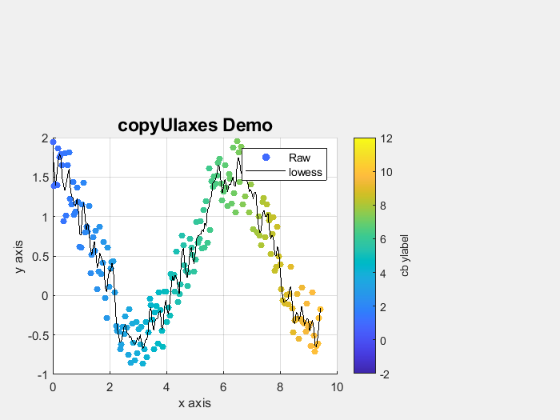

fh = uifigure();
uiax = uiaxes(fh);
hold(uiax,'on')
grid(uiax,'on')
x = linspace(0,3*pi,200);
y = cos(x) + rand(1,200);
ph = scatter(uiax,x,y,25,linspace(1,10,200),'filled');
lh = plot(uiax, x, smooth(x,y), 'k-');
title(uiax,'copyUIaxes Demo','FontSize',18)
xlabel(uiax,'x axis')
ylabel(uiax,'y axis')
zlabel(uiax,'z axis')
cb = colorbar(uiax);
cb.Ticks = -2:2:12;
caxis(uiax,[-2,12])
ylabel(cb,'cb ylabel')
lh = legend(uiax,[ph,lh],{'Raw','lowess'},'Location','NorthEast');

## Copy uiaxes to a new figure

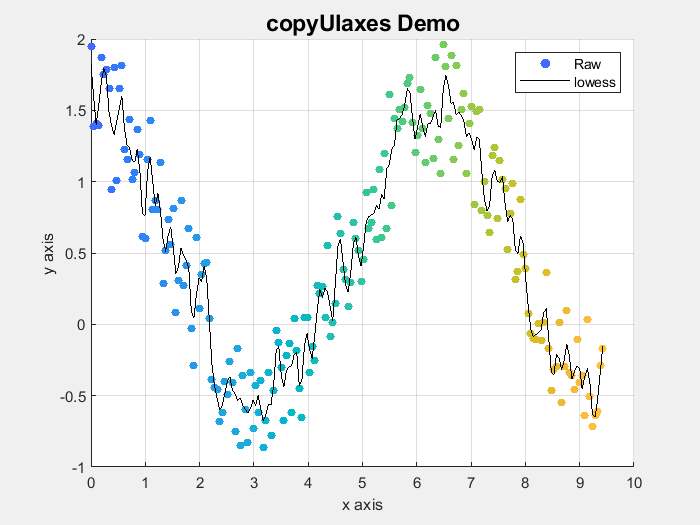

copyUIAxes(uiax);

## Include the colorbar

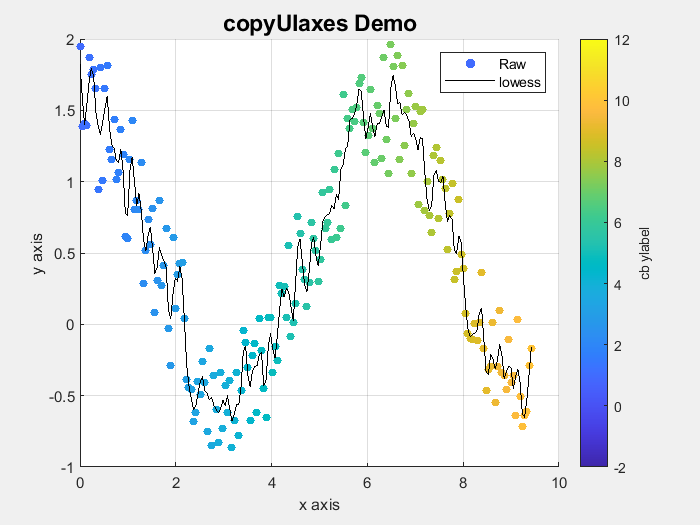

copyUIAxes(uiax,'Colorbar',cb);

## Copy uiaxes to predefined figure or axes & include colorbar

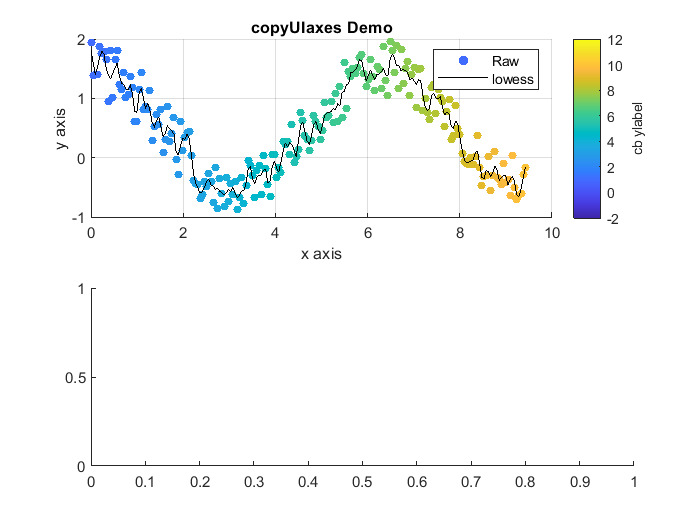

fig = figure();
ax = subplot(2,1,1); 
subplot(2,1,2)
copyUIAxes(uiax, ax, 'Colorbar', cb);

## Retain the uiaxes position relative to the figure & include colorbar

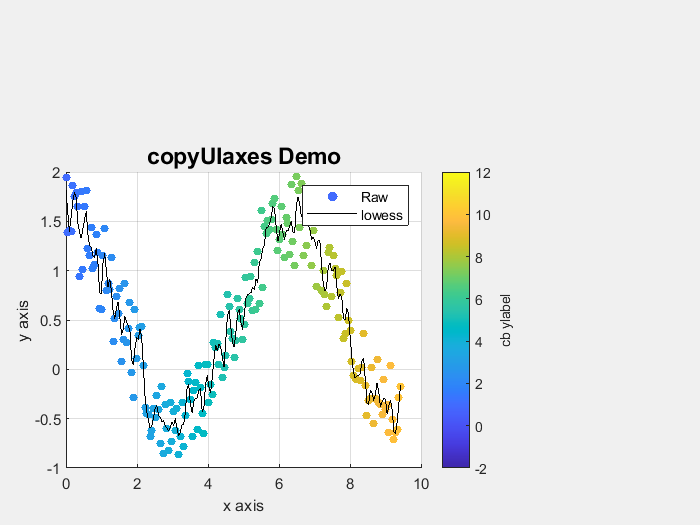

copyUIAxes(uiax, 'copyPosition', true, 'Colorbar', cb);

## List properties that were not copied

Some properties are not editable or cause problems when copied. 

**********************************************************************
The following properties (rows) were not copied from the following objects (columns)
either because they are not editable or because they were intentionally ignored.
See help('copyUIAxes') for details.
             axis                axesTitle          axesSubtitle         axesXLabel          axesYLabel          axesZLabel            legend         legendTitle 
    ______________________    ________________    ________________    ________________    ________________    ________________    ________________    ____________
    {'BeingDeleted'      }    {

copyUIAxes(uiax,'listIgnoredProps', true);

## View output handles to make adjustments to the copied figure

h = struct with fields:
          figure: [1×1 Figure]
            axes: [1×1 Axes]
       axesTitle: [1×1 Text]
    axesSubtitle: [1×1 Text]
      axesXLabel: [1×1 Text]
      axesYLabel: [1×1 Text]
      axesZLabel: [1×1 Text]
          legend: [1×1 Legend]
     legendTitle: [1×1 Text]

h = copyUIAxes(uiax)